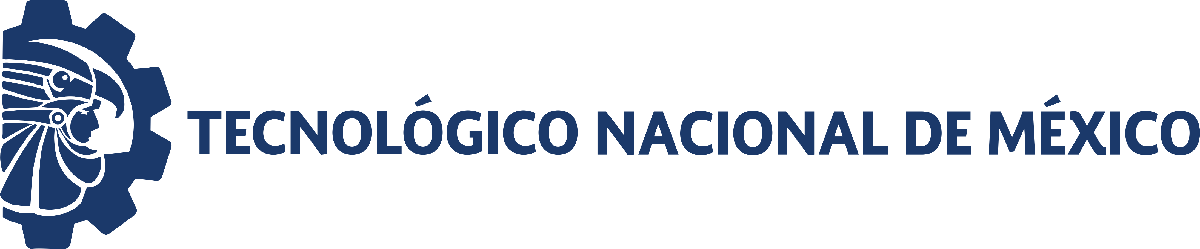                                 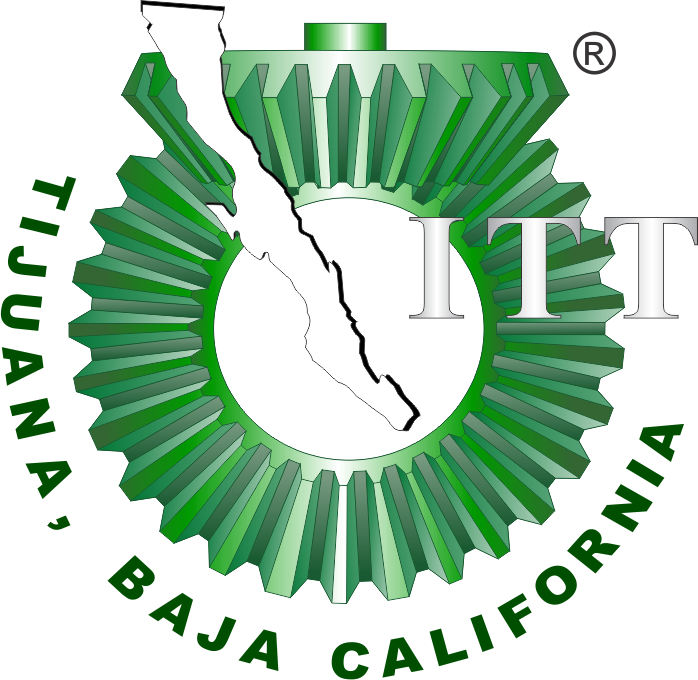

# Práctica: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

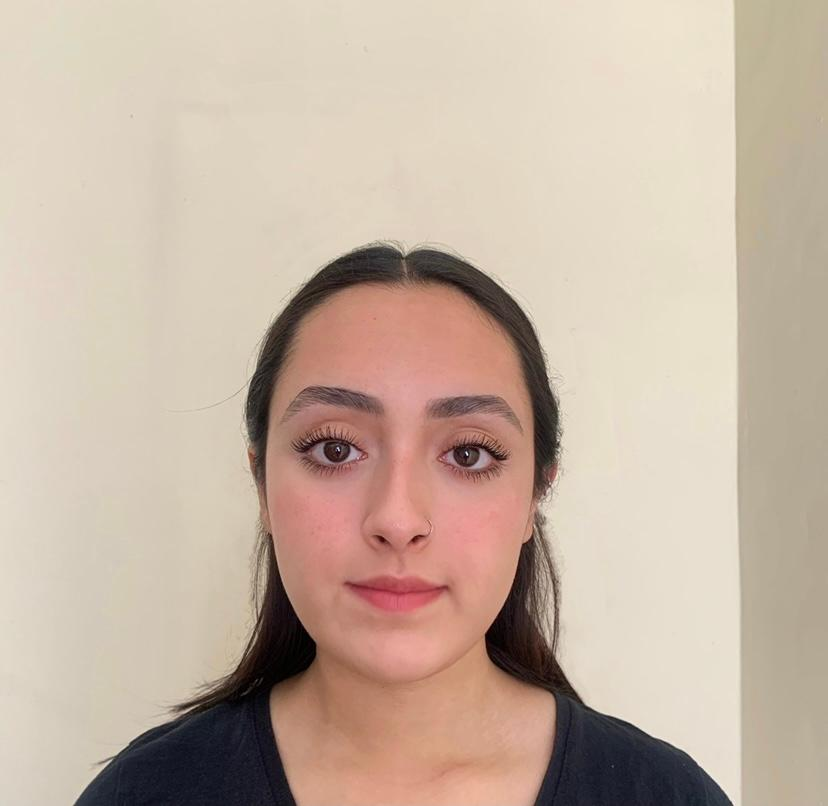 

Nombre del alumno: Jovita Maria Fernanda Antunez Rubio

Número de control: 22211745

Correo institucional: L22211745**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema5_4';
open_system(file);
parameters.stoptime = tend;
parameters.solver ='VariableStepAuto';
parameters.MaxStep= '1e-3'

parameters = struct with fields:
    stoptime: '10'
      solver: 'VariableStepAuto'
     MaxStep: '1e-3'


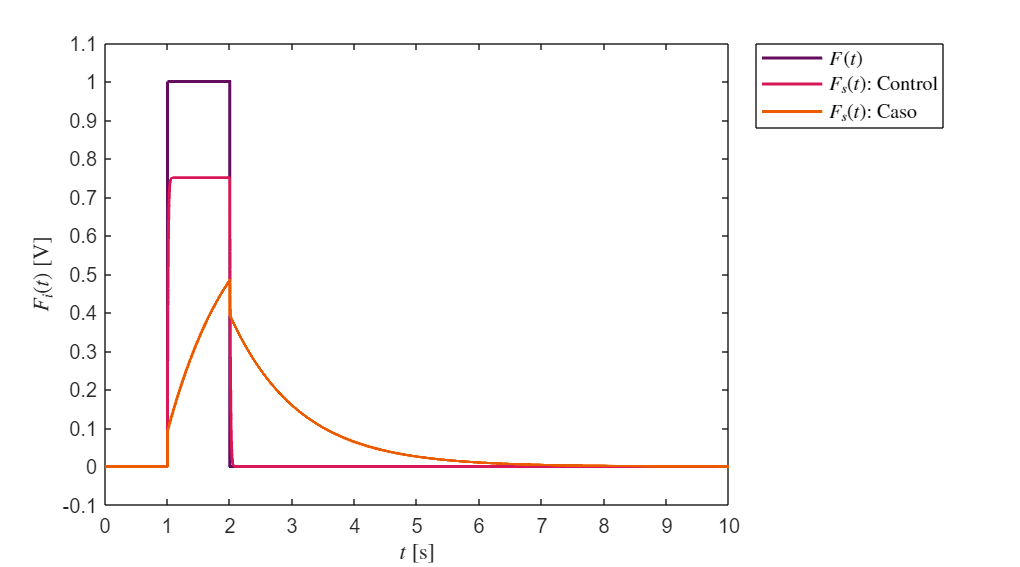

set_param('Sistema5_4/F','Amplitude','1');
set_param('Sistema5_4/F','Period','10');
Signal='Sistema musculoesquelético';
Signal2='Sistema musculoesquelético 2';
x = sim(file,parameters);

plotsignals(x.t,x.F,x.Fs1,x.Fs2,Signal)

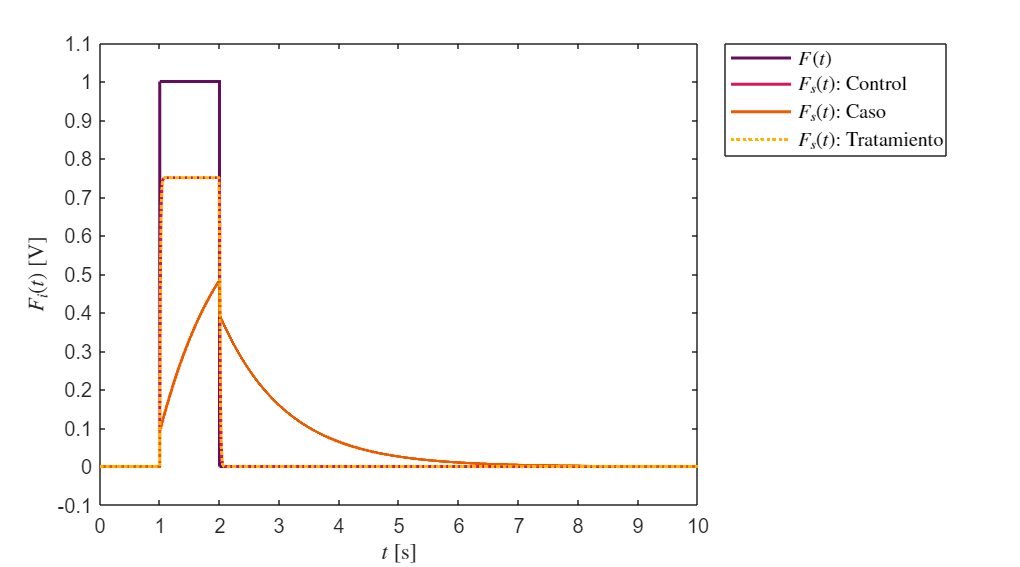

plotsignals2(x.t,x.F,x.Fs1,x.Fs2,x.Fs3,Signal2)

## Función: Respuesta a las señales

function plotsignals(t, F, Fs1, Fs2, Signal)
    fig = figure('Color', 'w');
    set(fig, 'Units', 'centimeters', 'Position', [1, 1, 18, 10]);

    mycolors = [100,13,95;
                217,22,86;
                235,91,0;
                255,178,0;
                42,98,154;
                247,82,112]/255;

    colororder(mycolors);
    
    hold on; box on;
    plot(t, F.Data, '-', 'LineWidth', 1.5);
    plot(t, Fs1.Data, '-', 'LineWidth', 1.5);
    plot(t, Fs2.Data, '-', 'LineWidth', 1.5);
    legend({'$F(t)$', ...
            '$F_{s}(t)$: Control', ...
            '$F_{s}(t)$: Caso'}, ...
            'Interpreter', 'latex', 'FontSize', 10, 'Location', 'bestoutside', 'Box', 'on');
    xlabel('$t$ [s]', 'Interpreter', 'latex', 'FontSize', 11);
    ylabel('$F_i(t)$ [V]', 'Interpreter', 'latex', 'FontSize', 11);
    xlim([0,10]); xticks(0:1:10);
    ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);

    exportgraphics(fig, [Signal, '.pdf'], 'ContentType', 'vector');
    exportgraphics(fig, [Signal, '.png'], 'ContentType', 'vector');
end

function plotsignals2(t, F, Fs1, Fs2, Fs3, Signal)
    fig = figure('Color', 'w');
    set(fig, 'Units', 'centimeters', 'Position', [1, 1, 18, 10]);

    mycolors = [100,13,95;
                217,22,86;
                235,91,0;
                255,178,0;
                42,98,154;
                247,82,112]/255;

    colororder(mycolors);
    
    hold on; box on;
    plot(t, F.Data, '-', 'LineWidth', 1.5);
    plot(t, Fs1.Data, '-', 'LineWidth', 1.5);
    plot(t, Fs2.Data, '-', 'LineWidth', 1.5);
    plot(t, Fs3.Data, ':', 'LineWidth', 1.5);
    legend({'$F(t)$', ...
            '$F_{s}(t)$: Control', ...
            '$F_{s}(t)$: Caso', ...
            '$F_{s}(t)$: Tratamiento'}, ...
            'Interpreter', 'latex', 'FontSize', 10, 'Location', 'bestoutside', 'Box', 'on');
    xlabel('$t$ [s]', 'Interpreter', 'latex', 'FontSize', 11);
    ylabel('$F_i(t)$ [V]', 'Interpreter', 'latex', 'FontSize', 11);
    xlim([0,10]); xticks(0:1:10);
    ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);

    exportgraphics(fig, [Signal, '.pdf'], 'ContentType', 'vector');
    exportgraphics(fig, [Signal, '.png'], 'ContentType', 'vector');
end